## Project 4 Solutions

## Exercise 1.1

Setup the variables.

x = [];
L = [];
xbar = [];
P = [];
Pbar = [];
xhat = [];
x(:,1) = 100*rand(2,1);  %Random input
xbar(:,1) = [0;0];
L(:,1) = zeros(2,1);
W = [0 0;0 0.1];
Pbar(:,:,1) = W;  %Initialize Pbar to be W
V = 0.01;
A = [1 1;0 1];
C = [1 0];

Main loop

for ii = 1:100
    y = C*x(:,ii)+0.01*randn;  

Correction

    xhat(:,ii) = xbar(:,ii)+L(:,ii)*(y - C*xbar(:,ii));
    P(:,:,ii) = (eye(2) - L(:,ii)*C)*Pbar(:,:,ii);
    

Prediction

    xbar(:,ii+1) = A*xhat(:,ii);
    Pbar(:,:,ii+1) = A*P(:,:,ii)*A'+W;
    L(:,ii+1) = Pbar(:,:,ii+1)*C'*inv(C*Pbar(:,:,ii+1)*C'+V);
    x(:,ii+1) = A*x(:,ii)+[0;1]*0.1*randn(1);  %Update the state
end

Make the plots

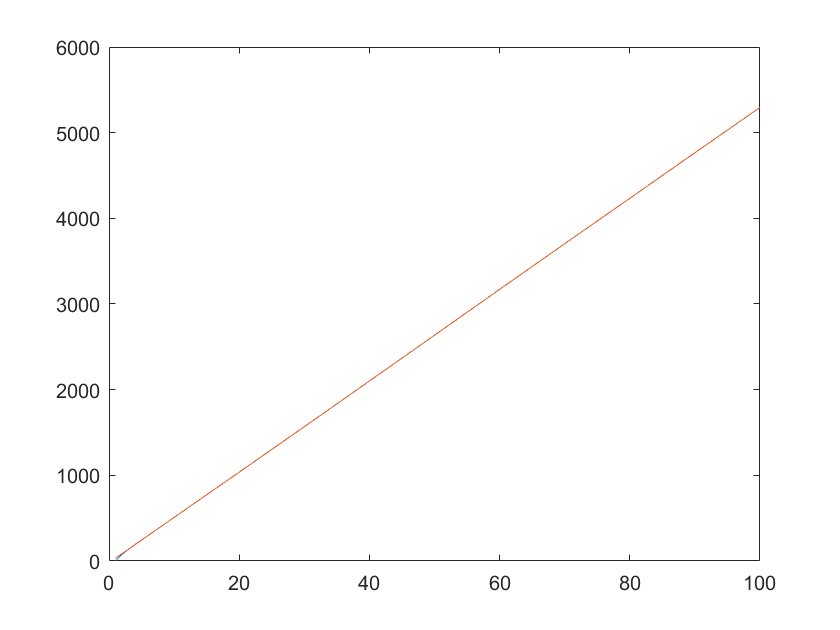

plot(1:100,xhat(1,:),1:100,x(1,1:end-1))

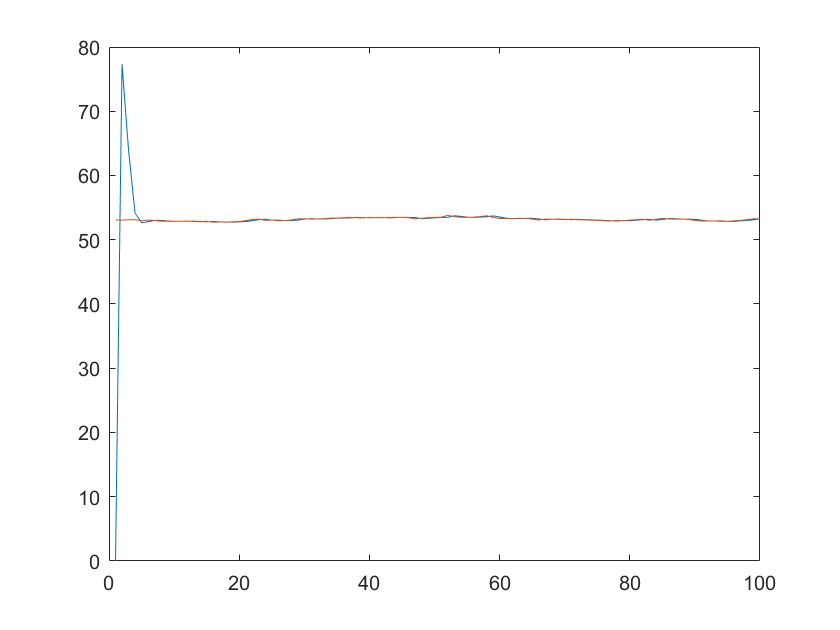

plot(1:100,xhat(2,:),1:100,x(2,1:end-1))

Clearly the states have converged!  I separated these so it would be easier to see the individual states.

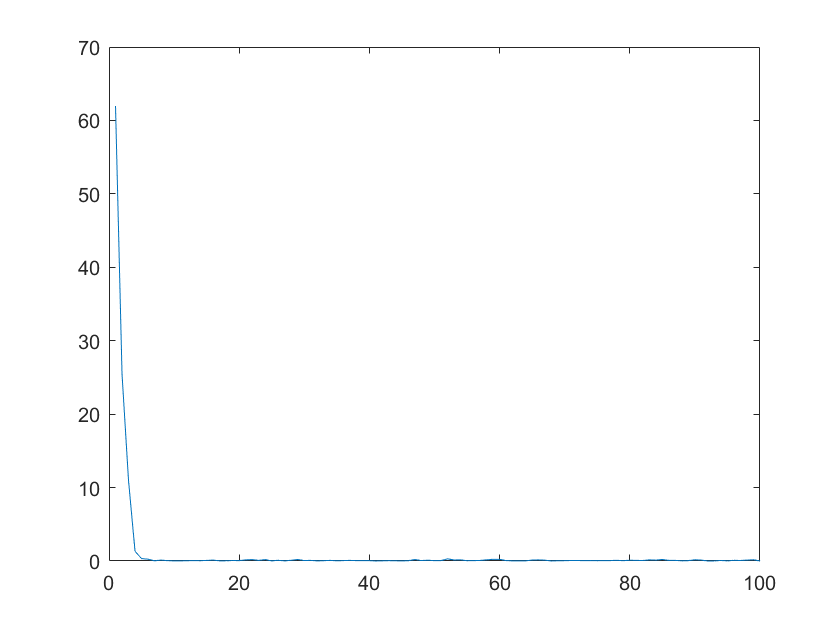

for ii = 1:100
    e(ii) = norm(x(:,ii)-xhat(:,ii));
end
plot(1:100,e)

## Exercise 1.2

Setup the problem.

T = 0.002;
W = diag([T^2/2*2.5,T*2.5]);
V = 2e-4;
N = ceil(1/T)+1;
A = [1 T;0 1];
B = [T^2/2;T];
C - [1 0];

x = [];
L = [];
xbar = [];
P = [];
Pbar = [];
xhat = [];
x(:,1) = zeros(2,1);  %Start at rest
xbar(:,1) = [0;0];
L(:,1) = zeros(2,1);
Pbar(:,:,1) = W;  %Initialize Pbar to be W

Start the loop.

for ii = 1:N
    y(ii) = C*x(:,ii)+2e-4*randn;  

Correction

    xhat(:,ii) = xbar(:,ii)+L(:,ii)*(y(ii) - C*xbar(:,ii));
    P(:,:,ii) = (eye(2) - L(:,ii)*C)*Pbar(:,:,ii);
    

Prediction

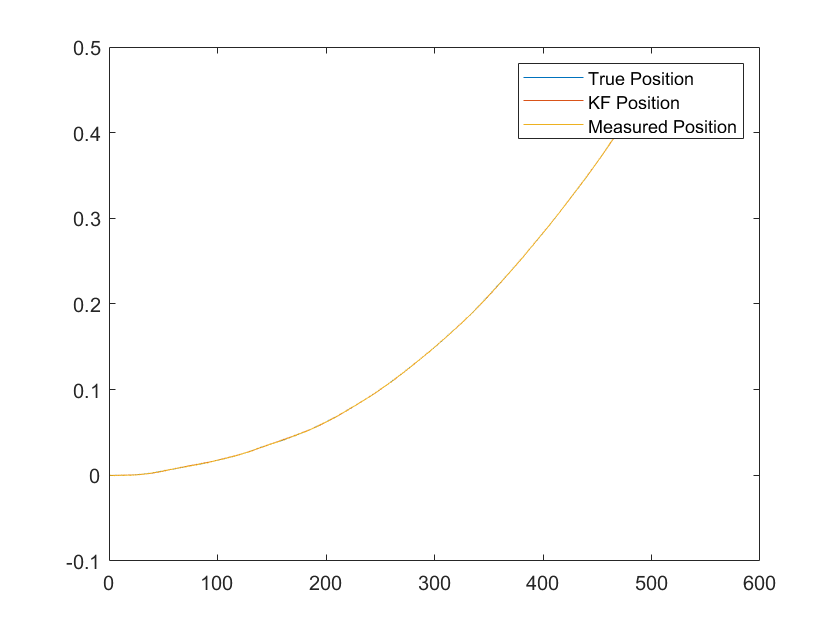

    xbar(:,ii+1) = A*xhat(:,ii)+B*1;
    Pbar(:,:,ii+1) = A*P(:,:,ii)*A'+W;
    L(:,ii+1) = Pbar(:,:,ii+1)*C'*inv(C*Pbar(:,:,ii+1)*C'+V);
    x(:,ii+1) = A*x(:,ii)+B*(1+2.5*randn(1));  %Update the state
end
plot(1:N,x(1,1:end-1),1:N,xhat(1,:),1:N,y)
legend('True Position','KF Position','Measured Position')

To make this easier to see, let's look at the error of the KF vs. the error of the measurement.

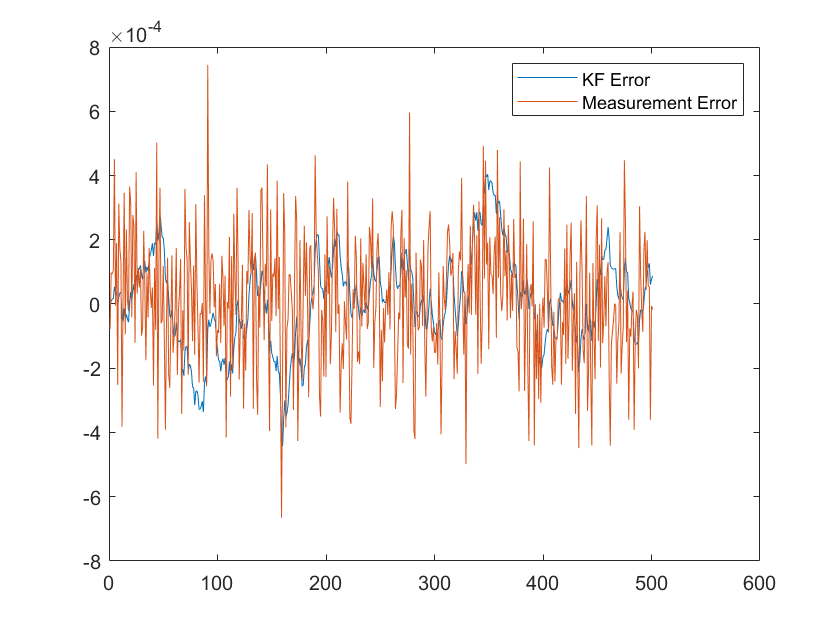

plot(1:N,x(1,1:end-1)-xhat(1,:),1:N,x(1,1:end-1)-y)
legend('KF Error','Measurement Error')

e_KF = std(x(1,1:end-1)-xhat(1,:))

e_KF = 1.4712e-04

e_meas = std(x(1,1:end-1)-y)

e_meas = 2.0250e-04

Even with this poor accelerometer, we have reduced the measurement error from the encoder.